rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data
load ripley.mat

length(Ytrain==1)

ans = 250

length(Ytest==1)

ans = 1000

sum(Ytrain==1)/length(Ytrain==1)

ans = 0.5000

sum(Ytest==1)/length(Ytest==1)

ans = 0.5000

blackColor = [0 0 0];
grayColor = [.7 .7 .7];
colors = [blackColor; grayColor]

colors =          0         0         0
    0.7000    0.7000    0.7000


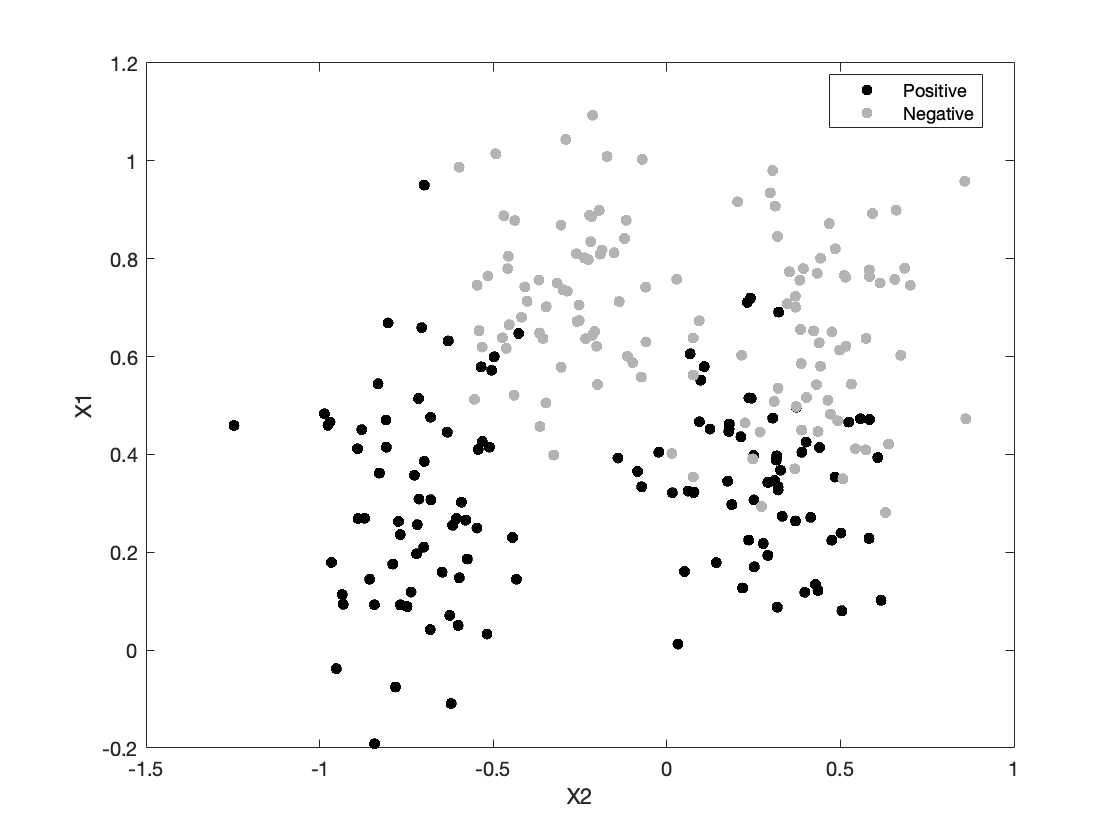

figure;
gscatter(Xtrain(:,1), Xtrain(:,2), Ytrain,colors)
xlabel('X2') 
ylabel('X1') 
legend('Positive','Negative')

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_141_1.png','Resolution',300)

run=[1:100];

simplex=[];
for r=run,
    [gam , sig2, cost] = tunelssvm({ Xtrain , Ytrain , 'c', [], [], 'lin_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex=[simplex; gam, sig2, cost];
end
tend = toc;


fprintf('\n LINEAR: median gamma = %.2f  ', median(simplex(:,1)))


 LINEAR: median gamma = 0.02  

fprintf('\n LINEAR: median cost = %.2f  ', median(simplex(:,2)))


 LINEAR: median cost = 0.14  

run=[1:100];
simplex_rbf=[];
for r=run,
    [gam ,sig2 , cost] = tunelssvm({ Xtrain , Ytrain , 'c', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex_rbf=[simplex_rbf; gam ,sig2 , cost];
end
tend = toc;

fprintf('\n RBF: median gamma = %.2f  ', median(simplex_rbf(:,1)))


 RBF: median gamma = 4.80  

fprintf('\n RBF: median sig = %.2f  ', median(simplex_rbf(:,2)))


 RBF: median sig = 0.67  

fprintf('\n RBF: median cost = %.2f  ', median(simplex_rbf(:,3)))


 RBF: median cost = 0.12  

run=[1:100];
simplex_poly=[];
for r=run,
    [gam, t, cost] = tunelssvm({ Xtrain , Ytrain , 'c', [], [], 'poly_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex_poly=[simplex_poly; gam ,t(:,1), t(:,2) , cost];
end
tend = toc;

fprintf('\n Poly: median gamma = %.2f  ', median(simplex_poly(:,1)))


 Poly: median gamma = 6.30  

fprintf('\n Poly: median t = %.2f  ', median(simplex_poly(:,2)))


 Poly: median t = 1.64  

fprintf('\n Poly: median degree = %.2f  ', median(simplex_poly(:,3)))


 Poly: median degree = 5.00  

fprintf('\n Poly: median cost = %.2f  ', median(simplex_poly(:,4)))


 Poly: median cost = 0.12  

gam = 4.80;
sig2 = 0.67;

% Train the classification model.
[ alpha , b ] = trainlssvm ({ Xtrain , Ytrain , 'c', gam , sig2 ,'RBF_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ Xtrain , Ytrain , 'c', gam , sig2 ,'RBF_kernel'} , { alpha , b } , Xtest ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , Ytest ) 

ans = 0.9686

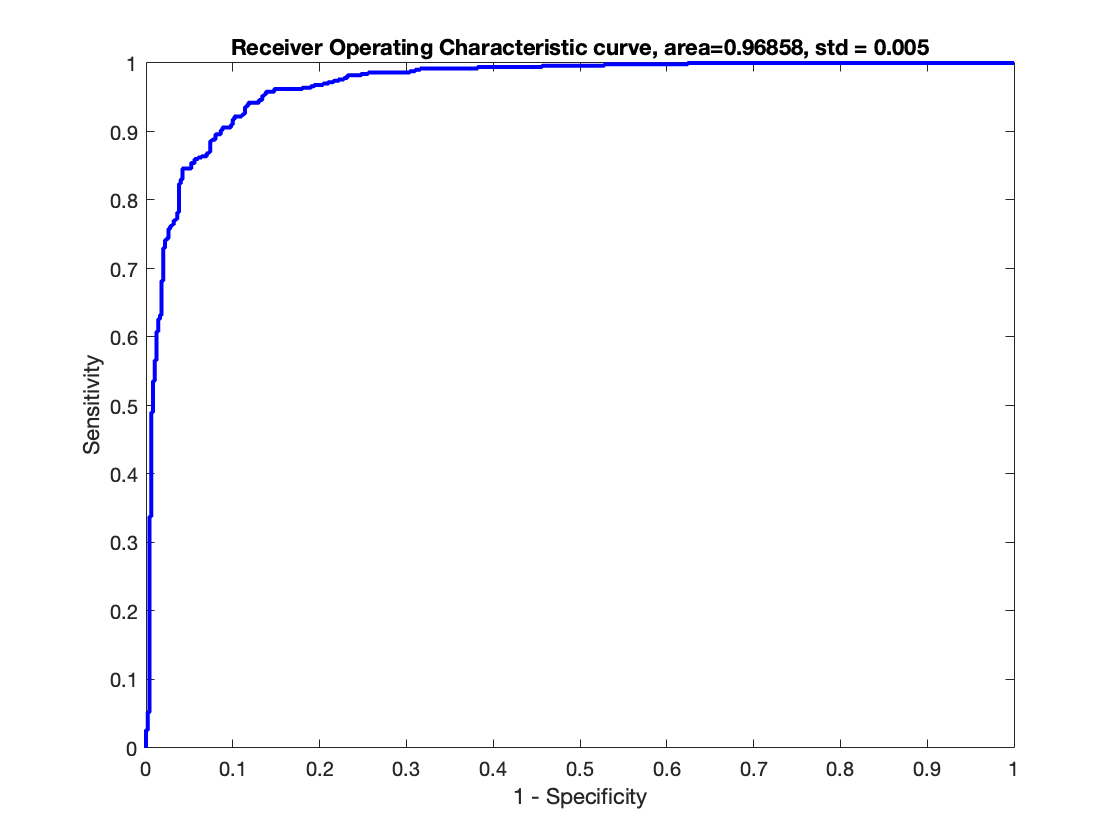

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_141_2.png','Resolution',300)

gam = 6.30

gam = 6.3000

t=1.64

t = 1.6400

degree=5

degree = 5

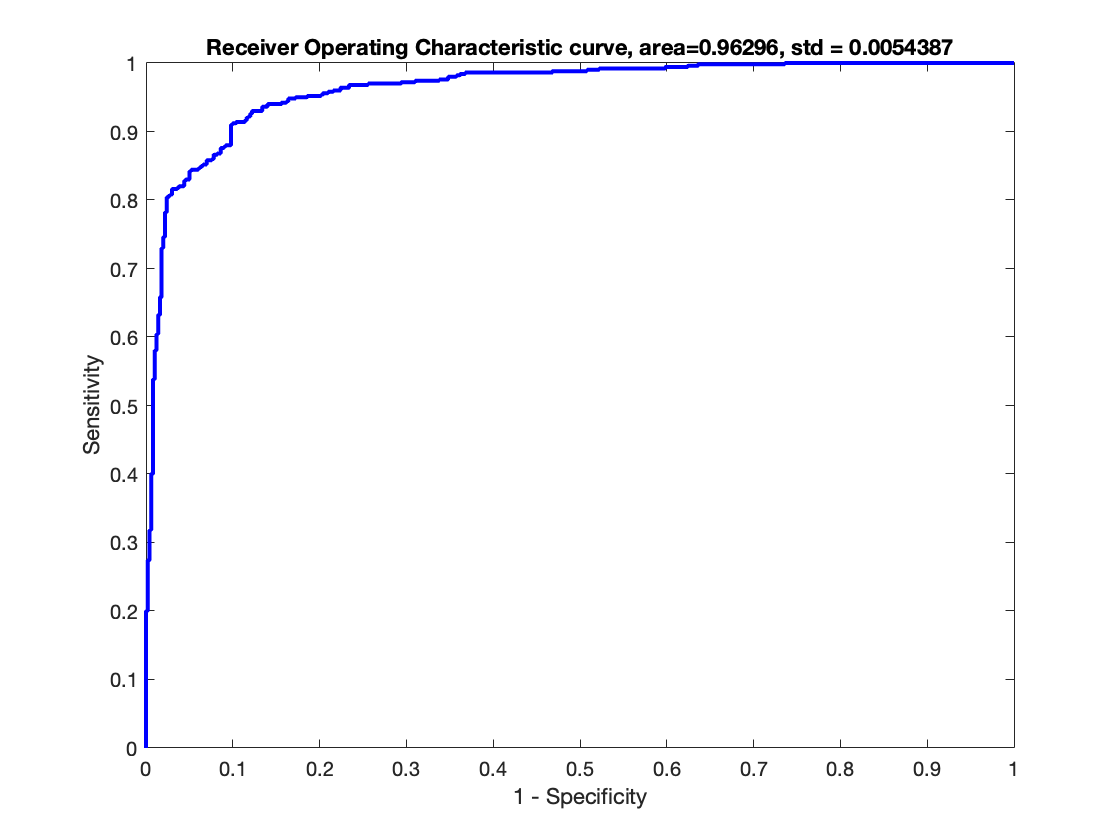

ans = 0.9630


% Train the classification model.
[ alpha , b ] = trainlssvm ({ Xtrain , Ytrain , 'c', gam , [t; degree] ,'poly_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ Xtrain , Ytrain , 'c', gam, [t; degree]  ,'poly_kernel'} , { alpha , b } , Xtest ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , Ytest ) 

f = gcf;
